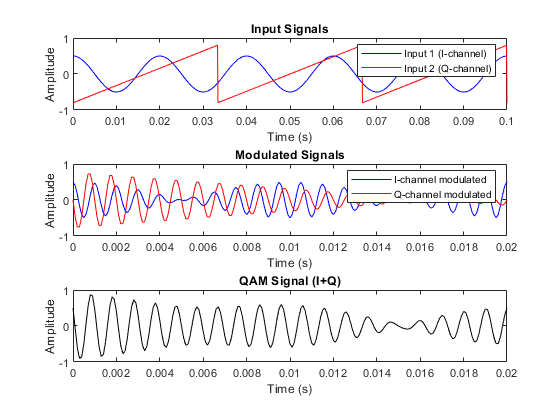

%% Simulation Parameters
fs = 10000;          % Sampling frequency (Hz)
fc = 1000;           % Carrier frequency (Hz)
T = 1;               % Simulation duration (seconds)
t = 0:1/fs:T-1/fs;   % Time vector
N = length(t);       % Number of samples

%% QAM Transmitter (Modulator)
% Generate two input signals (example signals)
input1 = 0.5*cos(2*pi*50*t);      % Input signal 1 (50 Hz cosine)
input2 = 0.8*sawtooth(2*pi*30*t); % Input signal 2 (30 Hz sawtooth)

% Local oscillator signals
carrier_I = cos(2*pi*fc*t);       % In-phase carrier
carrier_Q = sin(2*pi*fc*t);       % Quadrature carrier (90° phase shifted)

% Product modulators
modulated_I = input1 .* carrier_I; % I-channel modulation
modulated_Q = input2 .* carrier_Q; % Q-channel modulation

% Combine to form QAM signal
qam_signal = modulated_I + modulated_Q;

%% Channel (Add some noise)
SNR = 20; % Signal-to-Noise Ratio (dB)
qam_signal_noisy = awgn(qam_signal, SNR, 'measured');

%% QAM Receiver (Demodulator)
% Local oscillator signals (same as transmitter)
carrier_I_rx = cos(2*pi*fc*t);    % In-phase carrier
carrier_Q_rx = sin(2*pi*fc*t);    % Quadrature carrier

% Product demodulators
demod_I = qam_signal_noisy .* carrier_I_rx; % I-channel demodulation
demod_Q = qam_signal_noisy .* carrier_Q_rx; % Q-channel demodulation

% Low-pass filtering to recover baseband signals
cutoff_freq = 100; % Cutoff frequency for LPF (Hz)
[b, a] = butter(4, cutoff_freq/(fs/2)); % 4th order Butterworth LPF

% Filter both channels
output1 = filtfilt(b, a, demod_I);
output2 = filtfilt(b, a, demod_Q);

%% Plot Results
% Transmitter signals
figure('Name', 'QAM Transmitter', 'NumberTitle', 'off');
subplot(3,1,1);
plot(t, input1, 'b'); hold on;
plot(t, input2, 'r');
title('Input Signals');
legend('Input 1 (I-channel)', 'Input 2 (Q-channel)');
xlabel('Time (s)'); ylabel('Amplitude');
xlim([0 0.1]);

subplot(3,1,2);
plot(t, modulated_I, 'b'); hold on;
plot(t, modulated_Q, 'r');
title('Modulated Signals');
legend('I-channel modulated', 'Q-channel modulated');
xlabel('Time (s)'); ylabel('Amplitude');
xlim([0 0.02]);

subplot(3,1,3);
plot(t, qam_signal, 'k');
title('QAM Signal (I+Q)');
xlabel('Time (s)'); ylabel('Amplitude');
xlim([0 0.02]);

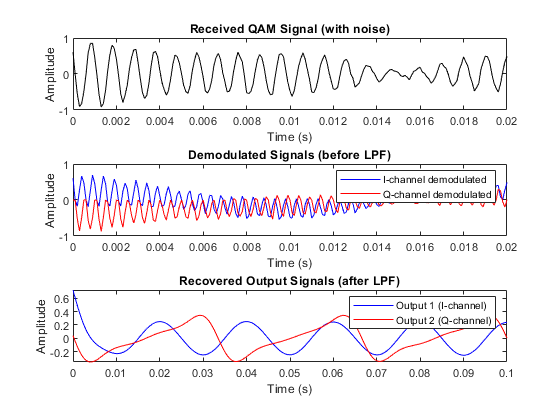


% Receiver signals
figure('Name', 'QAM Receiver', 'NumberTitle', 'off');
subplot(3,1,1);
plot(t, qam_signal_noisy, 'k');
title('Received QAM Signal (with noise)');
xlabel('Time (s)'); ylabel('Amplitude');
xlim([0 0.02]);

subplot(3,1,2);
plot(t, demod_I, 'b'); hold on;
plot(t, demod_Q, 'r');
title('Demodulated Signals (before LPF)');
legend('I-channel demodulated', 'Q-channel demodulated');
xlabel('Time (s)'); ylabel('Amplitude');
xlim([0 0.02]);

subplot(3,1,3);
plot(t, output1, 'b'); hold on;
plot(t, output2, 'r');
title('Recovered Output Signals (after LPF)');
legend('Output 1 (I-channel)', 'Output 2 (Q-channel)');
xlabel('Time (s)'); ylabel('Amplitude');
xlim([0 0.1]);

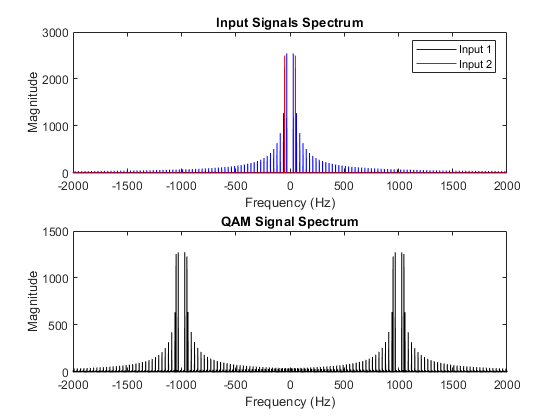


% Frequency domain analysis
figure('Name', 'Frequency Domain Analysis', 'NumberTitle', 'off');
f = (-N/2:N/2-1)*(fs/N); % Frequency vector

% Input spectrum
subplot(2,1,1);
input_spectrum = abs(fftshift(fft([input1; input2], N, 2)));
plot(f, input_spectrum(1,:), 'b'); hold on;
plot(f, input_spectrum(2,:), 'r');
title('Input Signals Spectrum');
legend('Input 1', 'Input 2');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
xlim([-2000 2000]);

% QAM spectrum
subplot(2,1,2);
qam_spectrum = abs(fftshift(fft(qam_signal, N)));
plot(f, qam_spectrum, 'k');
title('QAM Signal Spectrum');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
xlim([-2000 2000]);